s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 1/(s^2+3*s+2)


Gs =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties


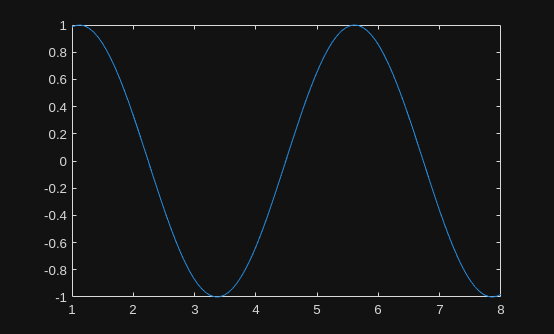


w = 1.4;
t=linspace(1,8,100);

x = sin(w * t);

figure 
plot(t,x)

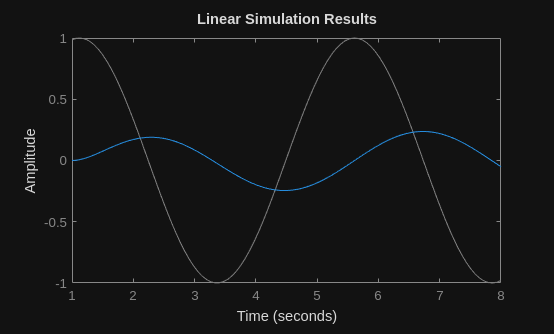

lsim(Gs,x,t)

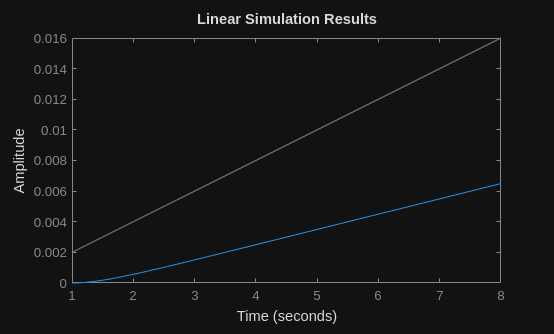

w1=[0.002,0.2,0.5,1.4,2.5,5];
x1 = sin(w1(1).*t);
x2 = sin(w1(2)*t);
x3 = sin(w1(3)*t);
x4 = sin(w1(4)*t);
x5 = sin(w1(5)*t);
x6 = sin(w1(6)*t);

lsim(Gs,x1,t)

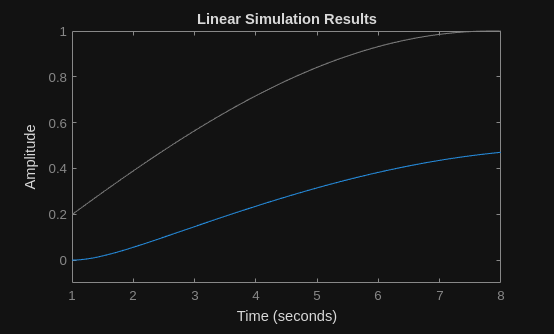

lsim(Gs,x2,t)

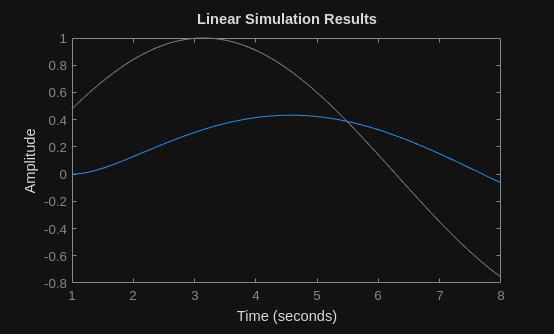

lsim(Gs,x3,t)

lsim(Gs,x4,t)

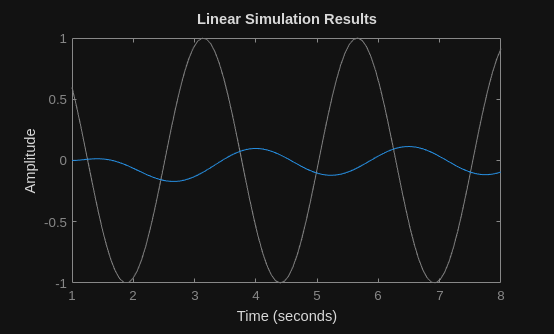

lsim(Gs,x5,t)

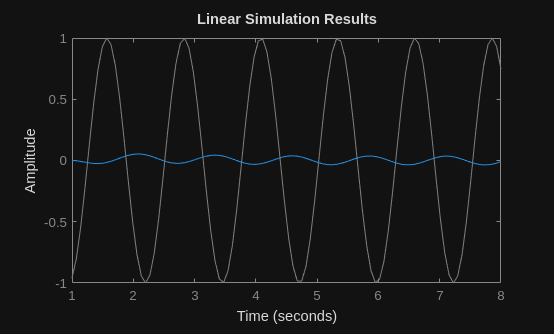

lsim(Gs,x6,t)

k = 1;

%st
Ra = k;
Ga = 1/(s^2+3*s+2);
Ha = 1;

GaW = Ra*Ga


GaW =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties



RootA = roots([1,3,2])

RootA =     -2
    -1


%st
Rb = k;
Gb =1/(s^2*2*s);
Hb = 1/(s+0.5);

GbW = Rb*Gb


GbW =
 
    1
  -----
  2 s^3
 
Continuous-time transfer function.
Model Properties



RootB= roots([2,1])

RootB = -0.5000

%st
Rc = k;
Gc = 10/(s^2*2.5*s+1);
Hc = 1/(s+1);

GcW = Rc*Gc


GcW =
 
      10
  -----------
  2.5 s^3 + 1
 
Continuous-time transfer function.
Model Properties



RootC = roots([2.5,0,0,1])

RootC =   -0.7368 + 0.0000i
   0.3684 + 0.6381i
   0.3684 - 0.6381i


%nst
Rd = k*(1+3*s);
Gd = 1/(s^2-2*s+1);
Hd = 1;

GdW = Rd*Gd


GdW =
 
     3 s + 1
  -------------
  s^2 - 2 s + 1
 
Continuous-time transfer function.
Model Properties



RootD = roots([1,-2,1])

RootD =      1
     1


%st
Re = k;
Ge = (10*s^2+s+1)/(s^4+4*s^3+5*s^2+2*s);
He = 1/s;

GeW = Ge*Re


GeW =
 
       10 s^2 + s + 1
  -------------------------
  s^4 + 4 s^3 + 5 s^2 + 2 s
 
Continuous-time transfer function.
Model Properties



RootC = roots([1,4,5,2,0,])

RootC =    0.0000 + 0.0000i
  -2.0000 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


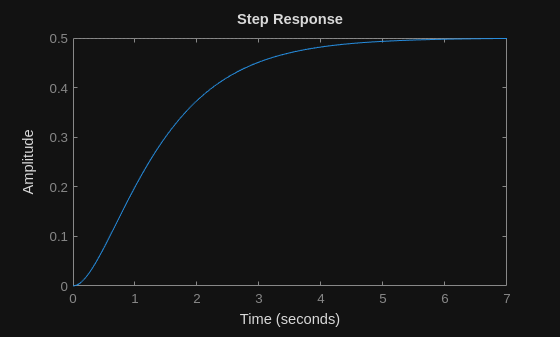

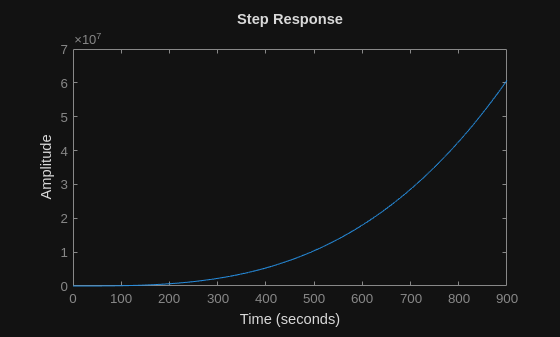

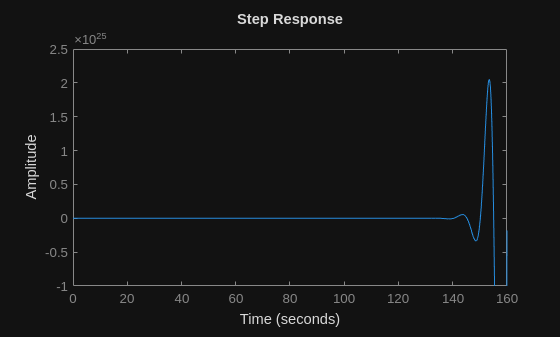

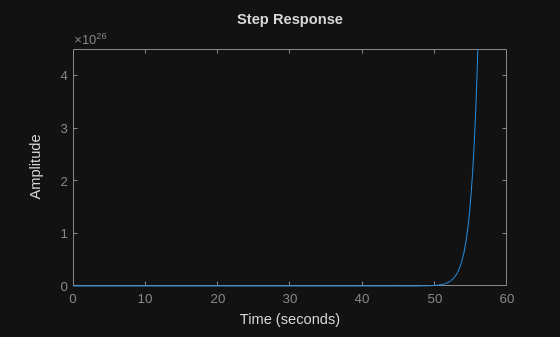

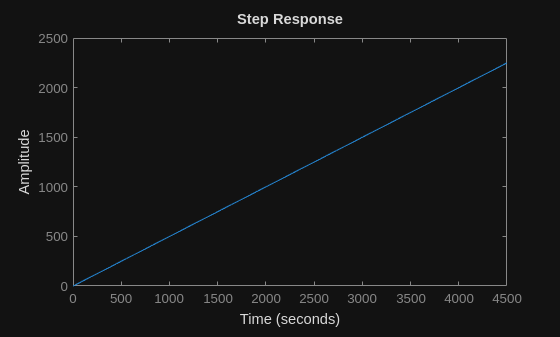

gvec=[GaW,GbW,GcW,GdW,GeW];

for i=1:5
    figure
    step(gvec(i))
end

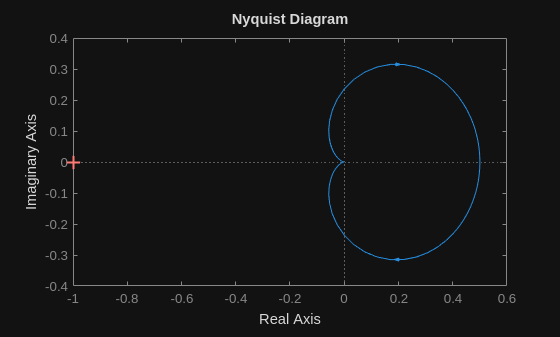

nyquistplot(GaW)

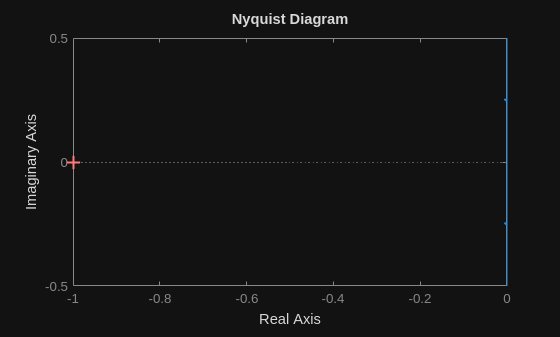

nyquistplot(GbW)

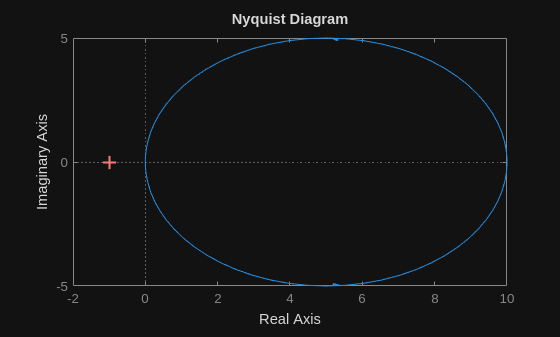

nyquistplot(GcW)

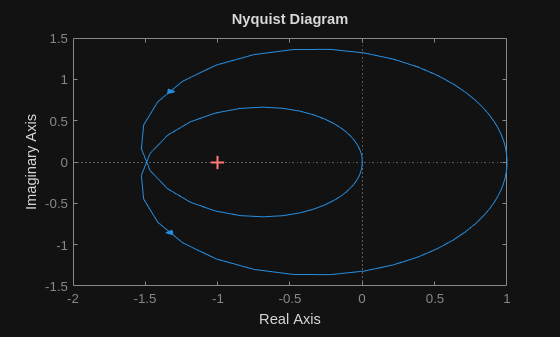

nyquistplot(GdW)

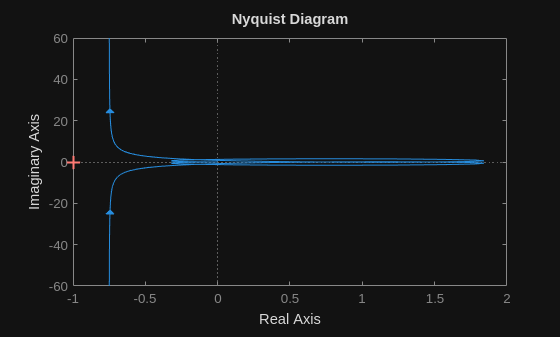

nyquistplot(GeW)



GaZ = feedback(GaW,Ha)


GaZ =
 
        1
  -------------
  s^2 + 3 s + 3
 
Continuous-time transfer function.
Model Properties


GbZ = feedback(GbW,Hb)


GbZ =
 
      s + 0.5
  ---------------
  2 s^4 + s^3 + 1
 
Continuous-time transfer function.
Model Properties


GcZ = feedback(GcW,Hc)


GcZ =
 
          10 s + 10
  --------------------------
  2.5 s^4 + 2.5 s^3 + s + 11
 
Continuous-time transfer function.
Model Properties


GdZ = feedback(GdW,Hd)


GdZ =
 
    3 s + 1
  -----------
  s^2 + s + 2
 
Continuous-time transfer function.
Model Properties


GeZ = feedback(GeW,He)


GeZ =
 
            10 s^3 + s^2 + s
  ------------------------------------
  s^5 + 4 s^4 + 5 s^3 + 12 s^2 + s + 1
 
Continuous-time transfer function.
Model Properties


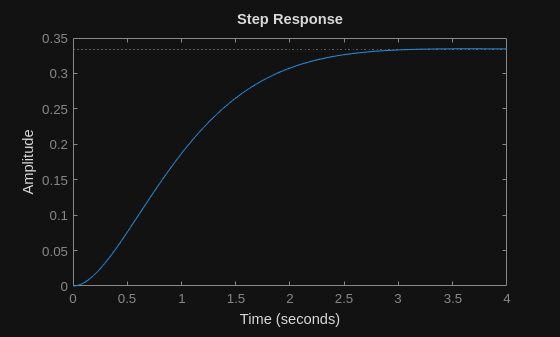


step(GaZ)

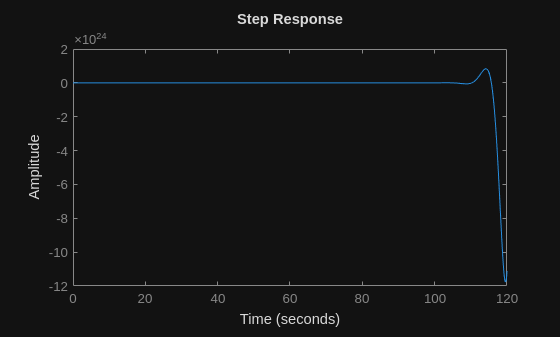

step(GbZ)

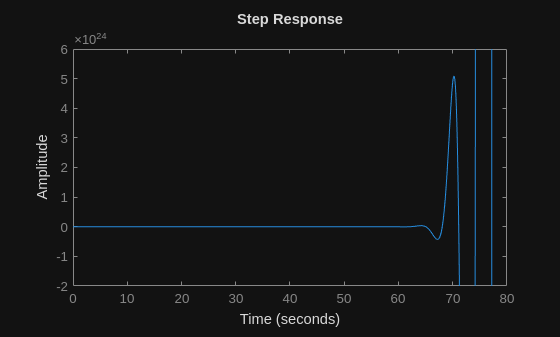

step(GcZ)

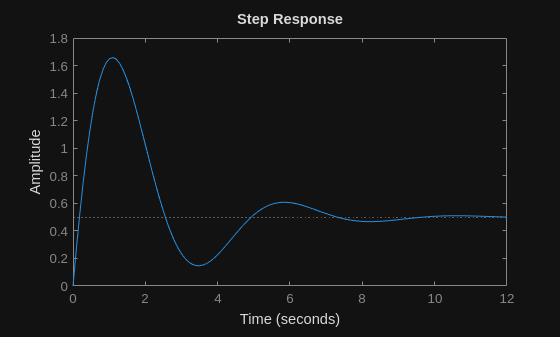

step(GdZ)

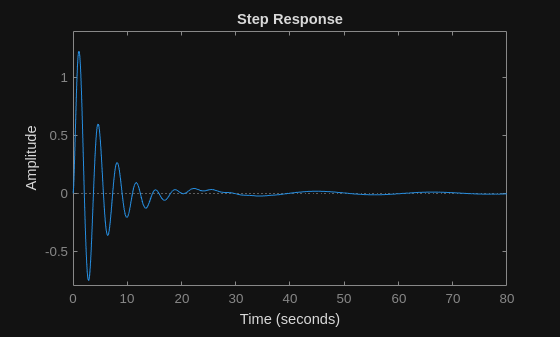

step(GeZ)